# Linear Control Design II - Group Work Problem Module 9

## Description		

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector. 

  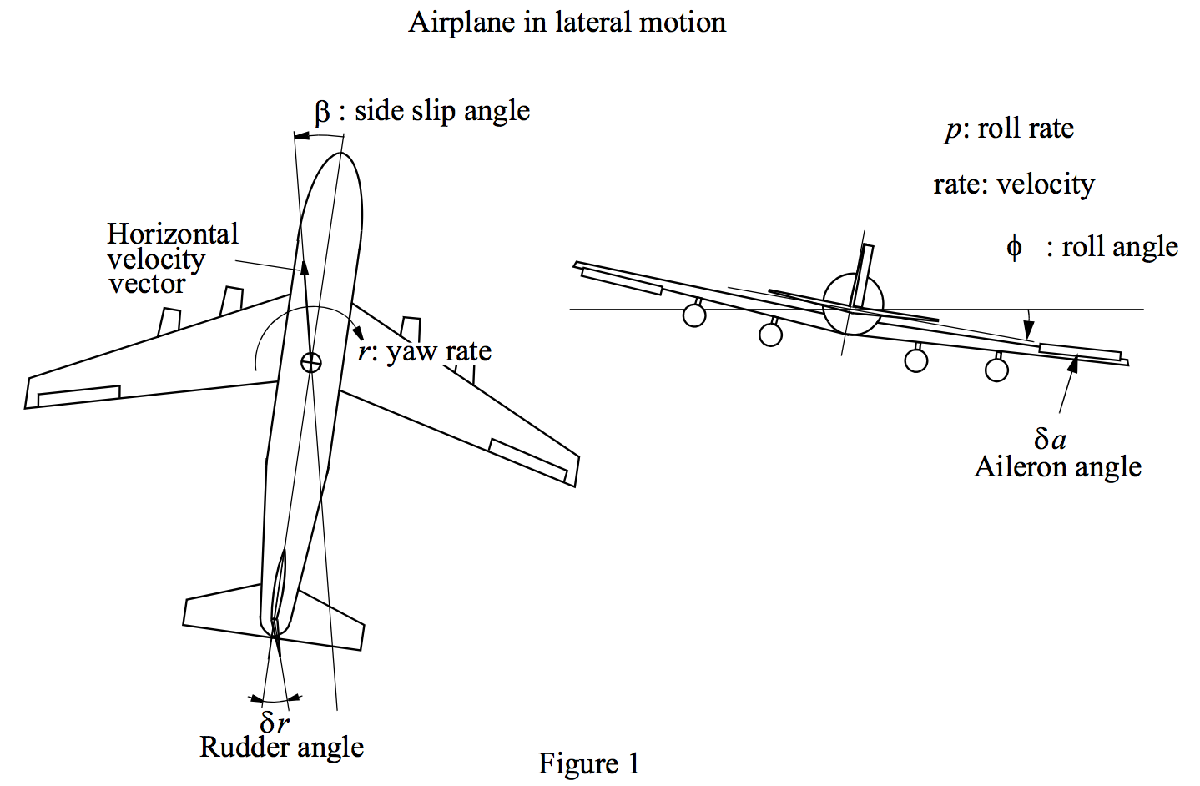

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:


$$\pmatrix{ \dot{\beta} \cr \dot{r} \cr \dot{p} \cr \dot{\varphi} } = \pmatrix{ -0.0558 &\ -0.9968 &\ 0.0802 &\ 0.0415 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr -3.0500 &\ 0.3880 &\ -0.4650 &\ 0 \cr 0 &\ 0.0805 &\ 1 &\ 0 } \pmatrix{ \beta \cr r \cr p \cr \varphi } + \pmatrix{ 0.00729 &\ 10^{-5} \cr -0.47500 &\ 0.123\cr 0.15300 &\ 1.063\cr 0 &\ 0} \pmatrix{ \delta r \cr \delta a }$$

$$y = \pmatrix{ 0 \ 1 \ 0 \ 0 \cr 0 \ 0 \ 0 \ 1 } \pmatrix{ \beta \cr r \cr p \cr \varphi}$$


where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), $\delta_r$ is the rudder deflection (rad) and $\delta_a$ is the aileron angle (rad).

format short g; clear all; close all; clc;

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

% Define state-space system:
sys_ss = ss(A,B,C,D)


sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729    1e-05
   x2   -0.475    0.123
   x3    0.153    1.063
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Problem 1  **Is the system controllable and observable?

*Use the controllability and observability matrices *$\mathbf{M_c}$* and *$\mathbf{M_o}$* (Matlab functions ctrb and obsv). How would you test whether *$\mathbf{M_c}$* has 4 linearly independent columns?*

*Also use the test with the left and the right eigenvectors (first part of PBH-test, i.e. the criteria CC3 and OC3) and the diagonal test (CC4 and OC4).*

**Solution****:**

% Your solution goes here:

Mc = ctrb(A,B)

Mc =       0.00729        1e-05      0.48534    -0.037354    -0.098535     0.058581     -0.40443    0.0049517
       -0.475        0.123     0.054119    -0.047942      0.29284   -0.0026226    -0.050301     0.025698
        0.153        1.063     -0.27768      -0.4466      -1.3302        0.303       1.0327     -0.32059
            0            0      0.11476       1.0729     -0.27332     -0.45046      -1.3066      0.30279


%Mc = [B A*B A^2*B A^3*B];
[rank(Mc) size(A,1)]

ans =      4     4


if rank(Mc) >= size(A,1)
    disp('System is Controllable')
end

System is Controllable


[V,M,W] = eig(A);
W'*B

ans =      -0.35594 + 3.3539e-05i     0.018139 +   0.034507i
     -0.35594 - 3.3539e-05i     0.018139 -   0.034507i
      0.36109 +          0i     -0.36387 +          0i
      -0.4335 +          0i      0.32313 +          0i


if round(W'*B,4) ~= zeros(size(W'*B))
    disp('System is Cotrollable')
end

System is Cotrollable


Bt = inv(V)*B

Bt =       0.63546 -    0.89716i     -0.11936 -   0.015897i
      0.63546 +    0.89716i     -0.11936 +   0.015897i
       2.1477 + 1.7807e-16i      -2.1643 - 7.1086e-17i
      -2.7555 - 4.9356e-16i       2.0539 + 2.9207e-16i


%Bt = [1 1;0 0;1 0;0 1]
if sum(abs(round(sum(Bt,2),4))==0) == 0
    disp('System is Controllable')
end

System is Controllable



Mo = obsv(A,C)

Mo =             0            1            0            0
            0            0            0            1
        0.598       -0.115      -0.0318            0
            0       0.0805            1            0
   -0.0051484      -0.5952     0.066404     0.024817
      -3.0019      0.37874     -0.46756            0
     -0.55817      0.10134     0.012454  -0.00021366
         1.82       2.7673    -0.035378     -0.12458


[rank(Mo) size(A,1)]

ans =      4     4


if rank(Mo) >= size(A,1)
    disp('System is Observable')
end

System is Observable


[V,M,W] = eig(A);
C*V

ans =     -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


if round(C*V,4) ~= zeros(size(C*V))
    disp('System is Observable')
end

System is Observable


Ct = C*inv(V)

Ct =        1.8635 -    0.98607i       -1.297 -     1.8308i     0.037779 +    0.22681i     0.040337 +   0.083096i
     -0.13401 - 2.3525e-17i       6.1906 + 1.0867e-15i       1.2159 + 1.4902e-16i      0.76415 + 2.2204e-16i


%Bt = [1 1;0 0;1 0;0 1]
if sum(abs(round(sum(Ct,1),4))==0) == 0
    disp('System is Observable')
end

System is Observable


**Problem 2  **Find the 4 transfer functions and determine the 4 sets of poles and zeros. 

**Solution:**

% Your solution goes here:

sys_ss.u = {'\delta_r', '\delta_a'};
sys_ss.y = {'r', '\phi'};
sys_tf = tf(sys_ss)


sys_tf =
 
  From input "\delta_r" to output...
          -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   r:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                     0.1148 s^2 - 0.2004 s - 1.373
   \phi:  ---------------------------------------------------
          s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
  From input "\delta_a" to output...
          0.123 s^3 + 0.03026 s^2 + 0.08238 s + 0.04195
   r:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                     1.073 s^2 + 0.2317 s + 1.024
   \phi:  ---------------------------------------------------
          s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



p = pole(sys_tf(1,1))

p =     -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i


for i = 1:2
    for j = 1:2
        z = zero(sys_tf(j,i))
    end
end

z =      -0.49808 +          0i
    -0.011893 +    0.48779i
    -0.011893 -    0.48779i


z =        4.4398
       -2.694


z =       0.10121 +    0.86618i
      0.10121 -    0.86618i
     -0.44845 +          0i


z =      -0.10797 +    0.97082i
     -0.10797 -    0.97082i


**Problem 3  **Set up a detailed Simulink model of the airplane. Base the model on figure 2.3 in the textbook. Note: One can use the MatrixGain-block as well as the usual Gain-block, but be sure that it is set up for matrix-multiplication. 

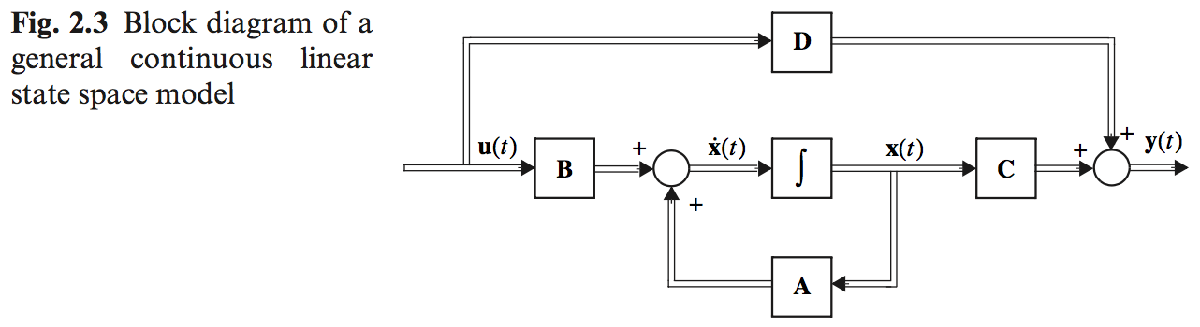

**Solution:**

% Your solution goes here:




**Problem 4  **Find the 4 step responses (use the angle 1° for both inputs) and plot them in a 2 by 2 array using Matlab’s subplot-function. 

**Solution:**

% Your solution goes here:




**Problem 5**  Last, simulate the response of the linear system by using the function on figure 2 at both inputs, but one at a time.

Is it possible to change the airplane’s heading by manipulating the ailerons only? 

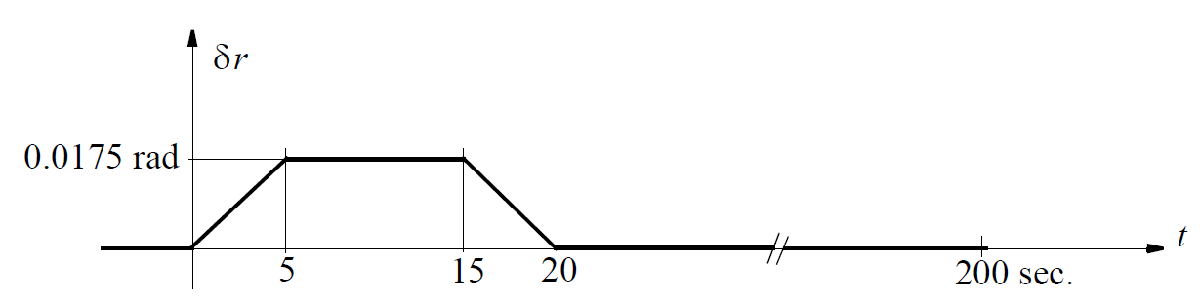	

**Solution:**

% Your solution goes here:


